# Hopper and MPC. 24.03.2025

clc; clear all; close all;

SimulinkOpen = false;
disturbOn = false;
GravityCompansation = true;
Euler_Angles = true;
RollUp = false;
DiagInertia = true;

## System parameters

Tjet = 45;
Troll = 3;
Tpy = 3;
e_x = 0;
e_y = 0;
e_z = 0;
l_2 = 0.3608544;    % 0.403;
l_3 = 0.3608544;    % 0.403;
l_4 = 0.3608544;    % 0.403;
l_5 = 0.3608544;    % 0.403;
l_6 = 0.2717;       % 0.263
l_7 = 0.2717;       % 0.263
l_8 = 0.2717;       % 0.263
l_9 = 0.2717;       % 0.263
d_2 = 0.305;    % 0.039;
d_3 = 0.305;    % 0.039;
d_4 = 0.305;    % 0.039;
d_5 = 0.305;    % 0.039;
d_6 = 0.2739;   %-0.018;
d_7 = 0.2739;
d_8 = 0.2739;
d_9 = 0.2739;
action_params = [
%     Thrust  ex ey   ez    Froll Fpitch Fyaw Lphi Lpitch Lyaw
     Tjet,  e_x, e_y, e_z,    0,  0,   0,   0,  0,  0;
     Troll, l_2, d_2,   0,  -45,  90,  0,   45, 90, 0;
     Troll, l_3, d_3,   0,   45,  90,  0,  -45, 90, 0;
     Troll, l_4, d_4,   0,  135,  90,  0, -135, 90, 0;
     Troll, l_5, d_5,   0, -135,  90,  0,  135, 90, 0;
     Tpy,   l_6, d_6,   0,    0,  0,   0,   90, 90, 0;
     Tpy,   l_7, d_7,   0,    0,  0,   0,    0, 90, 0;
     Tpy,   l_8, d_8,   0,    0,  0,   0,  -90, 90, 0;
     Tpy,   l_9, d_9,   0,    0,  0,   0,  180, 90, 0
];
clear e_x e_y e_z l_2 l_3 l_4 l_5 l_6 l_7 l_8 l_9 d_2 d_3 d_4 d_5 d_6 d_7 d_8 d_9;
geometry = action_params(:, 2:end);

%% Hopper's Moment of Inertia from Solidworks
tensors =  1e-9 * [
            2686253579.02, 650492741.40, 2687752194.18, -5482732.37, -691010.46, -2534148.08;
            2655165676.51, 642221197.41, 2656665844.71, -5067466.66, -698825.09, -2075573.42;
            2622453318.66, 633948606.77, 2623955143.39, -4624528.20, -707160.48, -1586439.96;
            2587948531.42, 625674861.26, 2589452126.87, -4151055.54, -716070.47, -1063587.82;
            2551459355.20, 617399837.21, 2552964847.80, -3643778.62, -725616.60, -503405.90;
            2512765405.26, 609123392.61, 2514272935.47, -3098943.17, -735869.52, 98251.60
];

mass = 1e-3 * [
        25610.09, 24810.09, 24010.09, 23210.09, 22410.09, 21610.09;
];

rcgs = Nw([0, pi/2, 0]) * 1e-3 * [
	    -1.84, 666.97, -1.53;
        -1.74, 661.43, -1.43;
        -1.64, 655.52, -1.32;
        -1.54, 649.21, -1.20;
        -1.42, 642.44, -1.07;
        -1.30, 635.17, -0.93
    ]';
rcgs = rcgs';

% Define sample 3x3 tensors at different time steps
Tensors = cat(3, RotateTensor(Vector2Tensor(tensors(1,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(2,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(3,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(4,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(5,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(6,:)), [0, pi/2, 0]) ...
               );
RealInertia = Tensors;
if DiagInertia
    for i=1:length(Tensors)
        Tensors(:,:, i) = DiagTensorInertia(Tensors(:,:, i));
    end
end

if RollUp
    geometry(2:5, 2) = ones(4,1) * rcgs(1, 1);
end
clear tensors;

%% Gravity 
g = 9.8065;                        % G-Force value
Lg = 1 / g;                        % Inverse G-force value
G = [0; -g; 0];                   % G-Force vector in Earth Frame

%% Mass
m_max = mass(1);                    % maximum mass
m_dry = mass(end);                  % minimum mass
fuel_capacity = 4;                  % Full fuel capacity
m_fuel = 4;                         % mass of fuel
m_full = m_dry + fuel_capacity;     % mass of filled hopper
m = m_dry + m_fuel;                 % current or initial mass

%% Inertia
% Central tensor inertia moment 
Js = tensor_interpolation(m, mass, Tensors);
% Tensor of Inertia for dry hopper
Js0 = tensor_interpolation(m_dry, mass, Tensors);

% jet rotor mass inertia
Jrotx = 9e-3; Jroty = 1e-2; Jrotz = 1e-2;
Jrot = diag([Jrotx, Jroty, Jrotz]);
params_rotor = [Jrotx, Jroty, Jrotz];

% Tensor Inertia Components
% Jxx = Js(1,1); Jyy = Js(2,2); Jzz = Js(3,3);

Thrust = 45;                                % Maximum Thrust, kg
mdot_max = 17.7 * 1e-3 * Tjet / Thrust;     % kg/s, max consumption
Fmax = Tjet * g;                           % N, 

%% Frequency 
n_max = 90000;               % rpm
wn_max = pi * n_max / 30;    % rad/s

beta = mdot_max / Fmax;     % mass consumption to thrust ratio
gamma = wn_max / Fmax;      % frequency to thrust ratio

rho = 1.2754;               % air density

% Damphers
c_v = 0.1;      % Linear
c_w = 0.01;     % Angular

% Damping matrix
Cv = diag([c_v, c_v, c_v]);
Cw = diag([c_w, c_w, c_w]);

% Center of mass
r_cg = rcgs(1, :);

[Hf, Hm] = ComponentForForces(geometry, rcgs(1,:))

Hf =     1.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000
         0    0.7071    0.7071   -0.7071   -0.7071         0         0         0         0
         0   -0.7071    0.7071    0.7071   -0.7071         0         0         0         0


Hm =          0   -0.3606    0.3585   -0.3611    0.3632         0         0         0         0
    0.0015   -0.2560    0.2560    0.2560   -0.2560    0.2732    0.0015   -0.2702    0.0015
    0.0018   -0.2560   -0.2560    0.2560    0.2560    0.0018   -0.2699    0.0018    0.2735


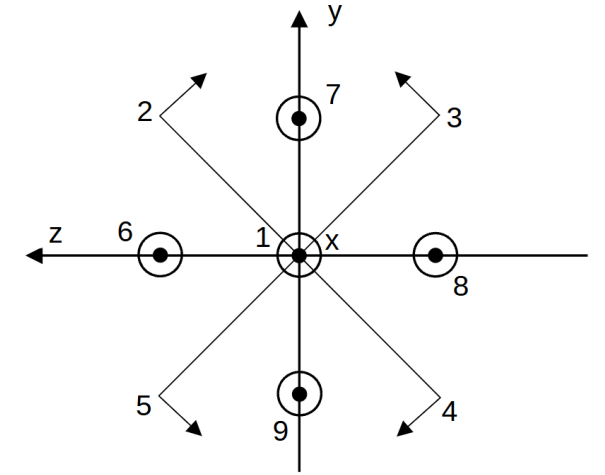

k_quat = 1;
gc = 1;
disturbances  = zeros(6,1);
%% Remove unnessary data
clear c_v c_w Thrust mdot_max Fmax wn_max Fmax;
% clear Jxx Jyy Jzz;
clear Jrotx Jroty Jrotz;

## Parameters

params = struct();
params.Inertia = RealInertia;
params.mass = mass;
params.rcgs = rcgs;
params.Jrot = Jrot;
params.Cv = Cv;
params.Cw = Cw;
params.Hf = Hf;
params.Hm = Hm;
params.Jdot_mlt = (Js - Js0) / (mass(1) - mass(end));
params.k_quat = k_quat;
params.m = m;
params.fuel = m_fuel;
params.g = g;
params.G = G;
params.gc = gc;
params.grav_on = 1;
params.rho = rho;
params.beta = beta;
params.gamma = gamma;
params.d = disturbances;
params.Gain = zeros(9,12);
params.geom = geometry;
params.Jo = RealInertia(:,:,1);
params.Jdot = zeros(3);
params.mdot = 0;

### Model Structure

modelparams = struct();
modelparams.Inertia = Tensors;
modelparams.mass = mass;
modelparams.rcgs = rcgs;
modelparams.Jrot = Jrot;
modelparams.Cv = Cv;
modelparams.Cw = Cw;
modelparams.Hf = Hf;
modelparams.Hm = Hm;
modelparams.Jdot_mlt = (Js - Js0) / (mass(1) - mass(end));
modelparams.k_quat = k_quat;
modelparams.m = m;
modelparams.fuel = m_fuel;
modelparams.g = g;
modelparams.G = G;
modelparams.gc = gc;
modelparams.grav_on = 1;
modelparams.rho = rho;
modelparams.beta = beta;
modelparams.gamma = gamma;
modelparams.d = disturbances;
modelparams.Gain = zeros(9,12);
modelparams.geom = geometry;
modelparams.Jo = Tensors(:,:,1);
modelparams.Jdot = zeros(3);
modelparams.mdot = 0;


% parameters = [Tensor2Vector(Js)'; Cv(1,1); Cv(2,2); Cv(3,3); Cw(1,1); Cw(2,2); Cw(3,3); gg; beta; gamma; rho; diag(Jdot_coeff); k_quat; gc; m];
clear Jo Jf Js Js0 mo mf Jdot_coeff gc k_quat disturbances Cv Cw sys_poles Ps Gcl Qs Rs;
clear x0 y0 ref_yaw ref_pitch ref_roll ref_eul init_yaw init_pitch init_roll dtau Tf;
clear geometry Hf Hm;

## Initial conditions

r = [0; 0; 0];              % position
v = [0; 0; 0];              % velocity
a = [0; pi/2.; 0];          % attitude [yaw, pitch, roll]
a1 = [pi/2; 0; 0];          % [pitch, yaw, roll] -> change the sequense of rotation
q = eul2quat(a1', 'ZYX')';  % quaternion
w = [0; 0; 0];              % angular velocity
mu = [m];                   % mass
% General State vector
s0 = [r; v; q; w];          % State Space vector
sm = [r; v; q; w; mu];      % State Space vector with Mass
sr = [r; v];
sa = [q; w];                % State Space vector for rotation
xIC = [r; v; a; w];
ref_eul = [1; 0; 0;  0.2;  0;  0; 0; pi/2; 0; 0; 0; 0];
u0 = zeros(9,1);
nu = 9;
nx = 12;
ny = 12;
Tf = 30;

## Linear system. Plant

[As, Bs] = build_lsys(xIC, u0, modelparams)

As =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0   -0.0039         0         0         0   -0.0000         0         0         0         0
         0         0         0         0   -0.0039         0         0    9.8065         0         0         0         0
         0         0         0         0         0   -0.0039    0.0000         0   -9.8065         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0       

Bs =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0   -0.5544    0.5511   -0.5551    0.5584         0         0         0         0


% Observer matrices
Cs = eye(12, 12);
Ds = zeros(12, 9);
% Ps = ss(As, Bs, Cs, Ds);

## MPC for 6-DOF System with Actuator Constraints

% Define sampling time
Ts = 0.05;                  % Adjust as needed
PredictionHorizon = 10;
ControlHorizon = 3;

### Setup simulation

mpcobj = mpc(ss(As, Bs, Cs, Ds, Ts));  % Assume plant is created using ss(A,B,C,D)

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
   for output(s) y1 y2 y3 y4 y5 y6 y7 y8 y9 and zero weight for output(s) y10 y11 y12 


% Set prediction and control horizons
mpcobj.PredictionHorizon = PredictionHorizon;
mpcobj.ControlHorizon = ControlHorizon;

% Define input constraints
umax = [450; 30; 30; 30; 30; 30; 30; 30; 30]; % Maximum force/moment limits
% umin = -umax; % Assume symmetric limits
umin = zeros(9,1);                            % 
% mpcController.ManipulatedVariables.Min = umin;
% mpcController.ManipulatedVariables.Max = umax;
for i = 1:nu
    mpcobj.ManipulatedVariables(i).Min = umin(i);
    mpcobj.ManipulatedVariables(i).Max = umax(i);
end

% Rate constraints (control change per Ts)
u_dot_max = [100; 10*ones(nu-1, 1)];  % [N/s] based on actuator dynamics
u_dot_min = -u_dot_max;

for i = 1:nu
    nlmpc_controller.MV(i).RateMin = u_dot_min(i);
    nlmpc_controller.MV(i).RateMax = u_dot_max(i);
end


% Define cost function weights
mpcobj.Weights.ManipulatedVariablesRate = 0.1 * ones(1, nu);
mpcobj.Weights.OutputVariables = 10 * ones(1, nx);
mpcobj.Model.Plant = ss(As, Bs, Cs, Ds, Ts);            % ← Include sample time!
xmpc = mpcstate(mpcobj);                            % Controller internal state

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

## Loop

Tsim = Tf / Ts;
x_history = zeros(nx+1, Tsim+1);
u_history = zeros(nu, Tsim);
x_history(:, 1) = [xIC; m];
u_opt = zeros(nu, 1);
x_0 = x_history(1:nx, 1);
tstop = 10;
mk = m;
tStart0 = tic;
%% Run control loop
for k = 1:Tsim
    % Solve NLMPC
    x_ref = ref_traj_generator(k*Ts, Ts, PredictionHorizon, tstop, ref_eul);

    % Update Model Parameters
    modelparams = UpdateModelParameters(modelparams, u_opt(1), Ts);
    % Update Object Parameters
    params = UpdateModelParameters(params, u_opt(1), Ts); 

    % Create options object and pass parameters
    %     [A, B, C, D] = LinearizeModel(x_0, u0, modelparams);
    [A, B, C, D] = LinearizeModel(xIC, u0, modelparams);
    mpcobj.Model.Plant = ss(A, B, C, D, Ts);

    % ⏱️ Start timing the optimization
    tStart = tic;
    u_opt = mpcmove(mpcobj, xmpc, x_history(1:nx, k), x_ref);  % MPC step
    
    % ⏱️ Stop timing and log
    tSolve = toc(tStart);
    tProg = toc(tStart0);
    if ~mod(k, 60)
        fprintf('Step %d: Optimization took %.4f secs\nTime progress: %.4f ', k, tSolve, tProg);
    end
    % Define anonymous function for current control input
    odeFcn = @(t, x) NL_HopperDyn(x, u_opt, params);
    % Integrate over one sample period [t0, t0 + Ts]
    [tSol, xSol] = ode45(odeFcn, [0 Ts], x_history(:, k));
    % Take the final value as the next state
    x_history(:, k+1) = xSol(end, :)';
    u_history(:, k)   = u_opt;
    x_0 = x_history(1:nx, k+1);
end

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

Step 60: Optimization took 0.0010 secs
Time progress: 5.2159 Step 120: Optimization took 0.0015 secs
Time progress: 7.3146 Step 180: Optimization took 0.0010 secs
Time progress: 9.2577 Step 240: Optimization took 0.0014 secs
Time progress: 11.4025 

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

Step 300: Optimization took 0.0668 secs
Time progress: 16.5774 

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

Step 360: Optimization took 0.0012 secs
Time progress: 21.1539 Step 420: Optimization took 0.0014 secs
Time progress: 23.2482 

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

Step 480: Optimization took 0.0621 secs
Time progress: 27.1014 

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

Step 540: Optimization took 0.0379 secs
Time progress: 32.3715 

-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #5 is integrated white noise.
-->Assuming output disturbance added to measured output channel #6 is integrated white noise.
-->Assuming output disturbance added to measured output channel #7 is integrated white noise.
-->Assuming output disturbance added to measured output channel #8 is integrated white noise.
-->Assuming output disturbance added to measured output channel #9 is integrated white noise.
-->Assuming output disturbance added to measured output channel #10 is integrated white noise.
-->Assuming output disturbance added to measured output cha

Step 600: Optimization took 0.0516 secs
Time progress: 37.6077 

## Save MPC control

u_hist = [0:Ts:Ts*(Tsim-1); u_history];
save('mpc_linear_u_history.mat', 'u_hist');
clear u_hist;

z = x_history';                      % Get State Vector
T = 0:Ts:Tsim*Ts;
Fc = Lg * u_history;                % Get Forces From Newtons To kilos

## Plot Results

### Translational

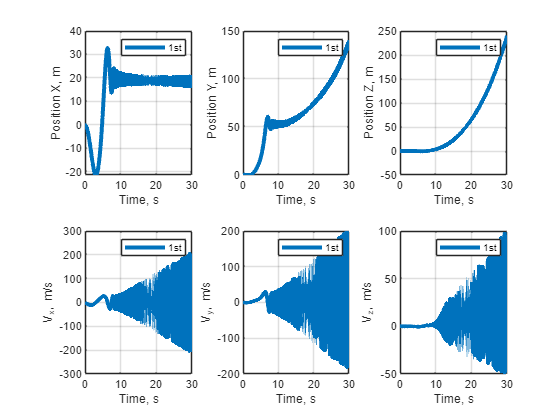

% Reference trajectory
figure;

subplot(2,3,1);
plot(T, z(:,1)); grid;
xlabel('Time, s');
ylabel('Position X, m');
legend({'1st'});

subplot(2,3,2);
plot(T, z(:,2)); grid;
xlabel('Time, s');
ylabel('Position Y, m');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,3);
plot(T, z(:,3)); grid;
xlabel('Time, s');
ylabel('Position Z, m');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,4);
plot(T, z(:,4)); grid;
xlabel('Time, s');
ylabel('V_x, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,5);
plot(T, z(:,5)); grid;
xlabel('Time, s');
ylabel('V_y, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,6);
plot(T, z(:,6)); grid;
xlabel('Time, s');
ylabel('V_z, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

set(groot, 'DefaultFigurePosition', [100, 100, 5000, 5000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 3);

### Rotational

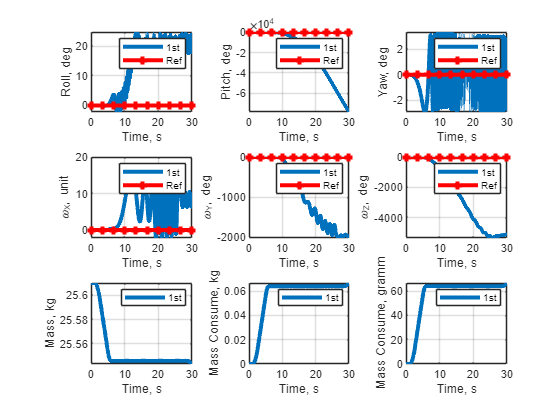

tspan = linspace(T(1), T(end), 10); 
mones = ones(1,10);
figure;

subplot(3,3,1);
plot(T, rad2deg(z(:, 7)), tspan, mones* rad2deg(ref_eul(7)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Roll, deg');
legend({'1st', 'Ref'});

subplot(3,3,2);
plot(T, rad2deg(z(:,8)), tspan, mones* rad2deg(ref_eul(8)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Pitch, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,3);
plot(T, rad2deg(z(:, 9)), tspan, mones* rad2deg(ref_eul(9)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Yaw, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,4);
plot(T, rad2deg(z(:,10)), tspan, mones* rad2deg(ref_eul(10)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_X, unit');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

% Euler's Rotation
subplot(3,3,5);
plot(T, rad2deg(z(:,11)), tspan, mones*rad2deg(ref_eul(11)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_Y, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,6);
plot(T, rad2deg(z(:, 12)), tspan, mones*rad2deg(ref_eul(12)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_Z, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,7);
plot(T, z(:,13)); grid;
xlabel('Time, s');
ylabel('Mass, kg');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(3,3,8);
plot(T, m - z(:, 13)); grid;
xlabel('Time, s');
ylabel('Mass Consume, kg');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(3,3,9);
plot(T, 1e3 * (m - z(:, 13))); grid;
xlabel('Time, s');
ylabel('Mass Consume, gramm');
% legend({'Const', 'Traj'});
legend({'1st'});

set(groot, 'DefaultFigurePosition', [50, 50, 2000, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 3);

### Forces

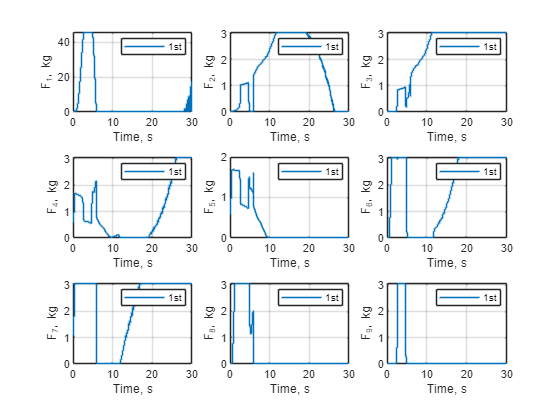

figure;
Tu = T(1:end-1);
subplot(3,3,1);
stairs(Tu, Fc(1,:)); grid;
xlabel('Time, s');
ylabel('F_1, kg');
legend({'1st'});

subplot(3,3,2);
stairs(Tu, Fc(2,:)); grid;
xlabel('Time, s');
ylabel('F_2, kg');
legend({'1st'});

subplot(3,3,3);
stairs(Tu, Fc(3,:)); grid;
xlabel('Time, s');
ylabel('F_3, kg');
legend({'1st'});

subplot(3,3,4);
stairs(Tu, Fc(4,:)); grid;
xlabel('Time, s');
ylabel('F_4, kg');
legend({'1st'});

subplot(3,3,5);
stairs(Tu, Fc(5,:)); grid;
xlabel('Time, s');
ylabel('F_5, kg');
legend({'1st'});

subplot(3,3,6);
stairs(Tu, Fc(6,:)); grid;
xlabel('Time, s');
ylabel('F_6, kg');
legend({'1st'});

subplot(3,3,7);
stairs(Tu, Fc(7,:)); grid;
xlabel('Time, s');
ylabel('F_7, kg');
legend({'1st'});

subplot(3,3,8);
stairs(Tu, Fc(8,:)); grid;
xlabel('Time, s');
ylabel('F_8, kg');
legend({'1st'});

subplot(3,3,9);
stairs(Tu, Fc(9,:)); grid;
xlabel('Time, s');
ylabel('F_9, kg');
legend({'1st'});

### Force projection

Forces = params.Hf * Fc;
Moments = params.Hm * Fc;

### Plot Force's Projections

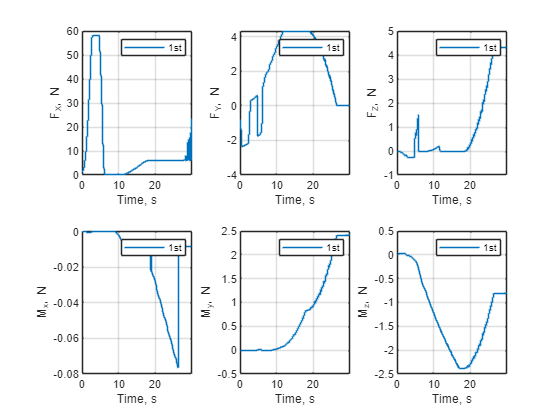

figure;

subplot(2,3,1);
stairs(Tu, Forces(1,:)); grid;
xlabel('Time, s');
ylabel('F_X, N');
legend({'1st'});

subplot(2,3,2);
stairs(Tu, Forces(2,:)); grid;
xlabel('Time, s');
ylabel('F_Y, N');
legend({'1st'});

subplot(2,3,3);
stairs(Tu, Forces(3,:)); grid;
xlabel('Time, s');
ylabel('F_Z, N');
legend({'1st'});


subplot(2,3,4);
stairs(Tu, Moments(1,:)); grid;
xlabel('Time, s');
ylabel('M_x, N');
legend({'1st'});

subplot(2,3,5);
stairs(Tu, Moments(2,:)); grid;
xlabel('Time, s');
ylabel('M_y, N');
legend({'1st'});

subplot(2,3,6);
stairs(Tu, Moments(3,:)); grid;
xlabel('Time, s');
ylabel('M_z, N');
legend({'1st'});

## Wrap

function ref = traj(t, t_stop, x_ref)
    vxd = x_ref(4);
    vxd2 = -vxd;
    vyd = -0.5;
    vyd2 = -vyd;
    pitch_d = x_ref(8);
    t_pause = 5;
    if t < t_stop
        ref = [vxd*t; 0;  0;
               vxd;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    else
        ref = [vxd*t_stop; 0;  0;
               0;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    end
end


function ref = ref_traj_generator(t_now, Ts, horizon, t_stop, x_ref)
    ref = zeros(horizon, 12);  % Assuming 12 state outputs
    for i = 1:horizon
        t_next = t_now + (i-1)*Ts;
        ref(i, :) = traj(t_next, t_stop, x_ref)';  % Some function of time
    end
end


function xdot = NL_HopperDyn_ODE(t, x, u, param)
    % Dynamic Integration Step
    xdot = NL_HopperDyn(x, u, param);               % Call dynamics function
end


function xdot = NL_HopperDyn(x, u, param)
    % NL_HOPPERDYN_1 Summary of this function goes here
    %   Detailed explanation goes here
    % x(13) - State Vector 6DoF: px,py,pz, vx,vy,vz, roll,pitch,yaw,
    % wx,wy,wz, m
    % u(9)  - Control Vector: Fx,Fy,Fz, Mx,My,Mz
    % params - System Parameters: Jxx,Jyy,Jzz,Jxy,Jyz,Jxz,m,Cx,Cy,Cz,Cr,Cq,Cp,g,
    %       - beta, gamma, rho, h, d, k_quat

    %% State vector
    % r = x(1:3);           % position
    v = x(4:6);             % velocity
    a = x(7:9);             % Euler's angles
    w = x(10:12);           % angular velocity
    m = x(13);              % current mass
    
    %% Disturbances
    Fd = param.d(1:3);            % Disturbance Forces
    Md = param.d(4:6);            % Disturbance Moments
    %% Mass and Inertia matrices
    
    mdot = -u(1) * param.beta;
    rcg = mass_center_interpolate(x(13), param.mass, param.rcgs);
    [Hf, Hm] = ComponentForForces(param.geom, rcg);
    %% Control Forces
    uuu = [Hf; Hm] * u; 
    F = uuu(1:3);                       % Forces
    M = uuu(4:6);                       % Moments

    Jo = tensor_interpolation(m, param.mass, param.Inertia);
    Jdot = param.Jdot_mlt * mdot;                                            % debug
    
    Mass = diag([m, m, m]);
    %% Damping matrices
    Cv = param.Cv;
    Cw = param.Cw;
    %% DCM
    DCM = Nw(a);                                    % inertial to body DCM
    %% Gravity
    G = param.gc * DCM * param.G;                   % Get gravity in body frame    
    %% System of Equations 
    xdot = zeros(size(x,1), 1);                     % initialize
    xdot(1:3, 1)    = v;
    xdot(4:6, 1)    = -cross(w, v) + Mass \ (-Cv * v + F + Fd) + G;
    xdot(7:9, 1)    = Tw(a) * w;
    xdot(10:12, 1)  = Jo \ (-cross(w, Jo*w)  - Cw*w - Jdot * w + M + Md);
    xdot(13, 1)     = mdot;
end

function xdot = NL_HopperDyn_mpc_ODE(x, u, param)
    %% State vector
    % r = x(1:3);           % position
    v = x(4:6);             % velocity
    a = x(7:9);             % Euler's angles
    w = x(10:12);           % angular velocity
    %     m = x(13);              % current mass
    
    %% Disturbances
    Fd = param.d(1:3);            % Disturbance Forces
    Md = param.d(4:6);            % Disturbance Moments
    %% Mass and Inertia matrices
    
    %     mdot = -u(1) * param.beta;
    %% Control Forces
    uuu = [param.Hf; param.Hm] * u; 
    F = uuu(1:3);                       % Forces
    M = uuu(4:6);                       % Moments

    Jo = param.Jo;
    Jdot = param.Jdot;
    
    Mass = diag([param.m, param.m, param.m]);
    %% Damping matrices
    Cv = param.Cv;
    Cw = param.Cw;
    %% DCM
    DCM = Nw(a);                                    % inertial to body DCM
    %% Gravity
    G = param.gc * DCM * param.G;                   % Get gravity in body frame    
    %% System of Equations 
    xdot = zeros(size(x,1), 1);                     % initialize
    xdot(1:3, 1)    = v;
    xdot(4:6, 1)    = -cross(w, v) + Mass \ (-Cv * v + F + Fd) + G;
    xdot(7:9, 1)    = Tw(a) * w;
    xdot(10:12, 1)  = Jo \ (-cross(w, Jo*w)  - Cw*w - Jdot * w + M + Md);
    %     xdot(13, 1)     = param.mdot;
end

function newparams = UpdateModelParameters(params, u, dtau)
    %% Copy
    newparams = params;
    %% Update
    mdot = -u * params.beta;
    newparams.mdot = mdot;
    newparams.m = params.m + mdot * dtau;
    rcg = mass_center_interpolate(newparams.m, newparams.mass, newparams.rcgs);
    [newparams.Hf, newparams.Hm] = ComponentForForces(newparams.geom, rcg);
    newparams.Jo = tensor_interpolation(newparams.m, newparams.mass, newparams.Inertia);
    newparams.Jdot = newparams.Jdot_mlt * mdot; 
end